# The wave equation on a star graph

Solves the wave equation $u_{tt} - \triangle u = 0$ on a star graph, using the leapfrog method

### Define the time and space limits and discretizations

L = 12;
nX = 20;
dt = .002;
tfinal=12;
tprint = 0.25;
nSteps=tfinal/dt;
nSkip=tprint/dt;
t=0:tprint:tfinal;

### Set up the quantum graph

Phi =quantumGraphFromTemplate('star','nX',64,'LVec',L,'Discretization','Chebyshev');
L0 = Phi.laplacianMatrixWithZeros;
P0 = Phi.interpolationMatrixWithZeros;
PVC = Phi.interpolationMatrixWithVC;

### Define the initial conditions

Recall that the leapfrog method requires the solution be given at times $t=0$ and $t=dt$. When the solution is a traveling wave, as here, we just use the (almost) exact solution at the two times.  If we are given the ordinary intial conditons of $u(x,0)= u_0(x)$ and $u_t(x,0)= v_0(x)$, then we may define the approximate solution at $t=dt$ using a second order Taylor approximation to be $u_1(x) = u_0(x) + v_0(x)\Delta t + \triangle u_0 \frac{\Delta t^2}{2}$. In order to satisfy the discretized vertex conditions at $t= \Delta t$, we would modify this to


$$\mathbf{P}_{\rm{VC}} u_1 =
\mathbf{P}_{0} (u_0 + \Delta t \cdot v_0) + 
\frac{\Delta t^2}{2} \mathbf{L}_{0} u_0$$


Value at time 0:

f0= @(x)exp(-(x-L/2).^2);
f1= @(x)zeros(size(x));
Phi.applyFunctionsToAllEdges({f0,f1,f1});
u0=Phi.graph2column;

Value at time $\Delta t$:

f0= @(x)exp(-(x-L/2+dt).^2);
f1= @(x)zeros(size(x));
Phi.applyFunctionsToAllEdges({f0,f1,f1});
u1=Phi.graph2column;

### Evolve using the leapfrog method

U=u0;
for k=3:nSteps
    u2 = PVC\(P0*(u1 + (u1-u0)) + dt^2*L0*u1);
    u0 = u1;
    u1 = u2;
    if mod(k,nSkip)==0
        U=[U u2];
    end
end

### Animate the solution

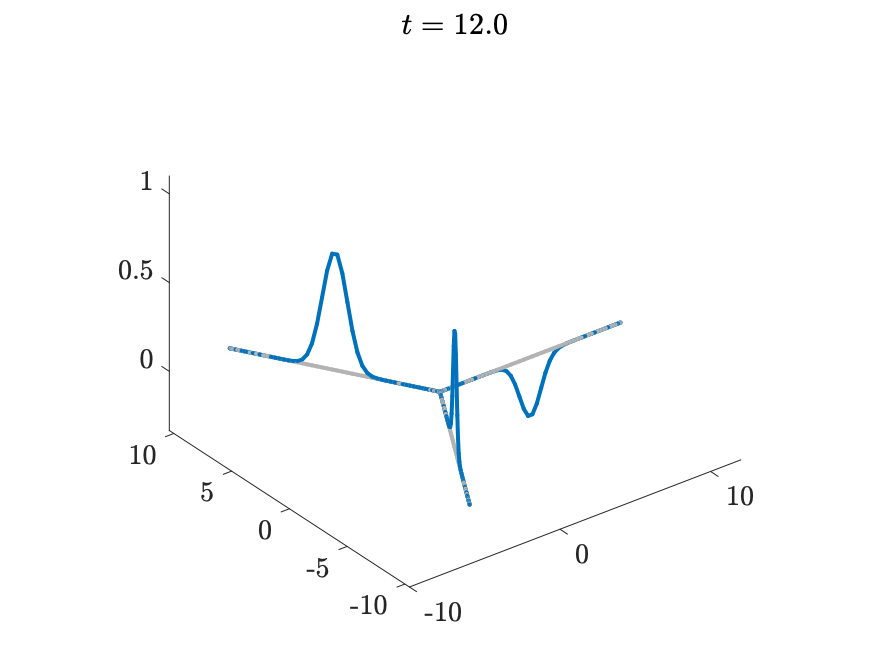

Phi.animatePDESolution(U,t)